Import image and convert to gray scale,double. Record size of image.

clc;clear;
load('HW04_FILES/Contrast2.mat');
load('HW04_FILES/Contrast1.mat');
[m,n]=size(Contrast2);
origin=Contrast1;
translated=Contrast2;

Calculate myNCC

R_beforeregis=myNCC(origin(4:end,3:end),translated(4:end,3:end));
diff1=origin-translated;

In order to translate the contrast2 back. We should translate -1.8 in x and -2.1 in y.

dx=-1.8;
dy=-2.1;

Now translate in x and y direction and calculate pixel value using intepolation.(backward transformation)

% Create a grid of coordinates
[X, Y] = meshgrid(1:n, 1:m);

% Compute the translated coordinates
X_regis = X + dx;
Y_regis = Y + dy;

% Initialize the output image with NaNs
regis_image = NaN(m, n);

% Find the integer coordinates surrounding the translated coordinates
x1 = floor(X_regis);
x2 = ceil(X_regis);
y1 = floor(Y_regis);
y2 = ceil(Y_regis);

% Identify valid interpolation points (within image bounds)
validMask = x1 >= 1 & x2 <= n & y1 >= 1 & y2 <= m;

% Interpolation weights
wx = X_regis - x1;
wy = Y_regis - y1;

% Retrieve pixel values at the four surrounding points for valid points
Q11 = NaN(m, n); Q21 = NaN(m, n);
Q12 = NaN(m, n); Q22 = NaN(m, n);

Q11(validMask) = double(translated(sub2ind([m, n], y1(validMask), x1(validMask))));
Q21(validMask) = double(translated(sub2ind([m, n], y1(validMask), x2(validMask))));
Q12(validMask) = double(translated(sub2ind([m, n], y2(validMask), x1(validMask))));
Q22(validMask) = double(translated(sub2ind([m, n], y2(validMask), x2(validMask))));

% Perform bilinear interpolation for valid points
regis_image(validMask) = (1 - wx(validMask)) .* (1 - wy(validMask)) .* Q11(validMask) + ...
                         wx(validMask) .* (1 - wy(validMask)) .* Q21(validMask) + ...
                         (1 - wx(validMask)) .* wy(validMask) .* Q12(validMask) + ...
                         wx(validMask) .* wy(validMask) .* Q22(validMask);
regis_image(isnan(regis_image)) = 0;

Calculate myNCC and subtract image with Contrast1

Difference=origin-regis_image;
% regis_image=uint8(regis_image);
% origin=uint8(origin);
% translated=uint8(translated);
R_afterregistration=myNCC(origin(4:end,3:end),regis_image(4:end,3:end));

 Print the result value and show the difference image with scale bar

fprintf('The result before registration is %d and after registration is %d.\n',R_beforeregis,R_afterregistration);

The result before registration is 9.778922e-01 and after registration is 9.998184e-01.


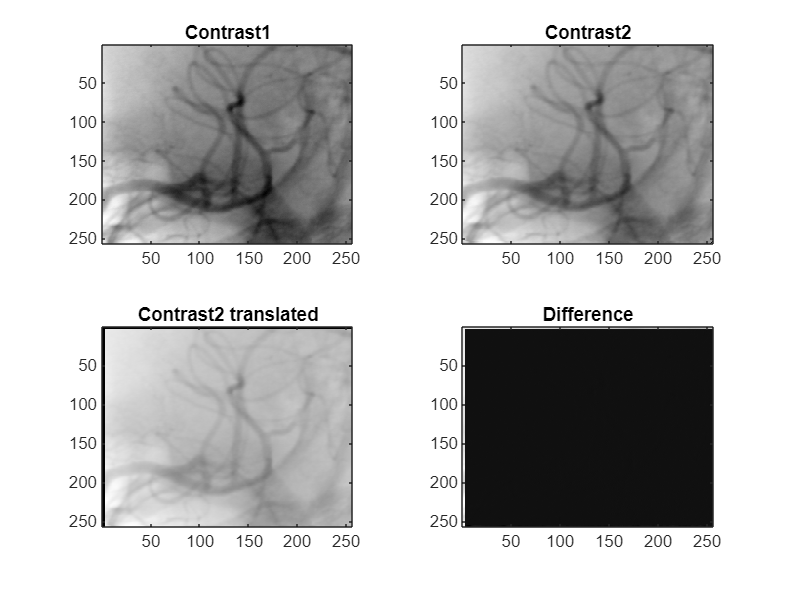


tiledlayout(2,2)
nexttile
imagesc(origin)
colormap('gray')
title('Contrast1')

nexttile
imagesc(translated)
title('Contrast2')
colormap('gray')
nexttile
imagesc(regis_image)
title('Contrast2 translated')
colormap('gray')
nexttile
imagesc(Difference)
title('Difference')
colormap('gray')

Q3

%initialize first guess for translation, [tx, ty]
t_i= [0,0];
%initialize array
param=struct();
param.scaling=1;

%calling the cost function SSE
costF= @(t) SSE(origin, translated, t(1),t(2), param );
% cost_test= SSE(origin, translated, -1.8, -2.1);
% display(cost_test)

%run fminsearch on optimal translation parameters
% and custom options to show iterations
options = optimset('Display','iter', ...         % show iteration info
                   'TolFun',1e-3, 'TolX',1e-3, ... % can tweak these
                   'OutputFcn',@regOutFun);
[t_optimal, fval]= fminsearch(costF, t_i, options);

Starting registration...


Not enough input arguments.

Error in regOutFun (line 20)
            [diffImg] = getDifferenceImage(x, fixedImg, movingImg, param);

Error in callAllOptimOutputFcns (line 13)
    stop(i) = feval(OutputFcn{i},xOutputfcn,optimValues,state,varargin{:});

Error in 

fprintf(['The optimal translation parameters t_x is %.4f, t_y is %4f, ' ...
    'and minimal cost function is %d\n'], ...
    t_optimal(1), t_optimal(2), fval);
figure;
subplot(1,2,1), imshow(origin,[]), title('Contrast 1');
subplot(1,2,2), imshow(translated,[]), title('Contrast 2');

% %Q3.b
% tx_optimal=t_optimal(1);
% ty_optimal= t_optimal(2);
% %registered new image with optimal translation, default bilinear method
% Im_optimal= imtranslate(translated, [tx_optimal,ty_optimal],'OutputView','same');
% 
% %difference images before and after optimization
% diffBefore= imabsdiff(origin, translated);
% diffAfter= imabsdiff(origin, Im_optimal);
% 
% %display orignal images and difference image in grayscale
% figure;
% subplot(2,2,1), imshow(origin,[]), title('Contrast 1');
% subplot(2,2,2), imshow(translated,[]), title('Contrast 2');
% subplot(2,2,3), imshow(diffBefore,[]), title('Difference Before Registration');
% subplot(2,2,4), imshow(diffAfter,[]), title('Difference After Registration');


Q4

t_i= [0,0];
%initialize array
param=struct();
param.scaling=1;

tolFun = [1e-1, 1e-3, 1e-5]; % Different TolFun values
tolX = [1e-1, 1e-3, 1e-5];   % Different TolX values
scaling= [1,10,100] % scaling factor

costF= @(t) SSE(origin, translated, t(1),t(2),param );

%initialize arrays to store result
results_fun=[];
results_x=[];
results_scaling=[];
%chaing tolerance for function value
for f=1:length(tolFun)
        options=optimset('TolFun', tolFun(f),'Display','off');
        [t_op, fvalue,exitflag, output]=fminsearch(costF, t_i, options)
        r1.TolFun= tolFun(f);
        r1.Cost= fvalue;
        r1.Iteration= output.iterations;
        if exitflag==1;
            r1.Outcomes='Sucess';
        else
            r1.Outcomes='Failure';
        end
        results_fun= [results_fun, r1];
end
table1= struct2table(results_fun);
disp(table1);
%changing tolerance for x value
for x= 1:length(tolX)
    options= optimset('TolX', tolX(x),'Display','off');
    [t_op, fvalue,exitflag, output]=fminsearch(costF, t_i, options)
    r2.TolX= tolX(x);
    r2.Cost=fvalue;
    r2.Iteration= output.iterations;
    if exitflag==1;
            r2.Outcomes='Sucess';
        else
            r2.Outcomes='Failure';
    end
    results_x=[results_x, r2];
end
table2= struct2table(results_x);
disp(table2);

%changing scaling factor
for s=1:length(scaling)
    param.scaling= scaling(s);
    options=optimset('Display','off');
    [t_op, fvalue,exitflag, output]=fminsearch(costF, t_i, options)
    r3.Scale= scaling(s);
    r3.Cost=fvalue;
    r3.Iteration= output.iterations;
    if exitflag==1;
            r3.Outcomes='Sucess';
        else
            r3.Outcomes='Failure';
    end
    results_scaling=[results_scaling, r3];
end
table3= struct2table(results_scaling);
disp(table3);
